% Housekeeping
clear
clc
close all

% Read data
L = readtable('Wing Load.xlsx')

L = 60×8 table
    Var1       Var2          Var3           Var4          Var5           Var6         Var7        Var8    
    ____    __________    ___________    __________    ___________    ___________    ______    ___________

      0      3.435e+05         -58014    2.8549e+05        -3621.3     -1.374e+05     23206     -1.142e+05
    0.5     3.4345e+05         -58014    2.8544e+05        -3621.3    -1.3738e+05     23206    -1.1418e+05
      1      3.433e+05         -58014    2.8529e+05        -3621.3    -1.3732e+05     23206    -1.1412e+05
    1.5     3.4305e+05         -58014    2.8504e+05        -3621.3    -1.3722e+05     23206    -1.1402e+05
      2      3.427e+05         -58014    2.8469e+05        -3621.3    


S = readtable('Wing Shear.xlsx')

S = 60×8 table
    Var1       Var2          Var3           Var4          Var5           Var6           Var7          Var8    
    ____    __________    ___________    __________    ___________    ___________    __________    ___________

      0      7.903e+06    -1.1053e+06    6.7977e+06    -6.4974e+06    -3.1612e+06    4.4213e+05    -2.7191e+06
    0.5     7.7313e+06    -1.0473e+06     6.684e+06    -6.4937e+06    -3.0925e+06    4.1893e+05    -2.6736e+06
      1     7.5596e+06    -9.8931e+05    6.5703e+06    -6.4901e+06    -3.0238e+06    3.9572e+05    -2.6281e+06
    1.5      7.388e+06    -9.3129e+05    6.4567e+06    -6.4865e+06    -2.9552e+06    3.7252e+05    -2.5827e+06
      2     7.2166e+06    -8.7328e+05    6.343


M = readtable('Wing Moment.xlsx')

M = 60×8 table
    Var1       Var2          Var3           Var4          Var5           Var6           Var7          Var8    
    ____    __________    ___________    __________    ___________    ___________    __________    ___________

      0     9.8248e+07    -9.9712e+06    8.8277e+07    -2.6333e+07    -3.9299e+07    3.9885e+06    -3.5311e+07
    0.5      9.434e+07    -9.4331e+06    8.4907e+07    -2.3085e+07    -3.7736e+07    3.7732e+06    -3.3963e+07
      1     9.0517e+07    -8.9239e+06    8.1593e+07     -1.984e+07    -3.6207e+07    3.5696e+06    -3.2637e+07
    1.5      8.678e+07    -8.4438e+06    7.8336e+07    -1.6595e+07    -3.4712e+07    3.3775e+06    -3.1334e+07
      2     8.3129e+07    -7.9926e+06    7.513


T = readtable('Wing Torque.xlsx')

T = 60×10 table
    Var1       Var2          Var3          Var4          Var5           Var6           Var7           Var8           Var9           Var10   
    ____    __________    __________    __________    ___________    ___________    ___________    ___________    ___________    ___________

      0     2.4176e+07    1.3341e+06     2.551e+07    -1.3808e+06    -3.0165e+05    -1.6824e+06    -4.2103e+06    -4.2103e+06    -4.2103e+06
    0.5     2.3621e+07    1.3341e+06    2.4955e+07    -1.3837e+06    -3.0165e+05    -1.6854e+06    -4.1048e+06    -4.1048e+06    -4.1048e+06
      1     2.3068e+07    1.3341e+06    2.4402e+07    -1.3866e+06    -3.0165e+0


All = readtable('Wing Summary.xlsx')

All = 60×7 table
    Var1       Var2          Var3           Var4          Var5           Var6          Var7    
    ____    __________    ___________    __________    ___________    __________    ___________

      0     6.7977e+06    -6.4974e+06    8.8277e+07    -3.5311e+07     2.551e+07    -4.2103e+06
    0.5      6.684e+06    -6.4937e+06    8.4907e+07    -3.3963e+07    2.4955e+07    -4.1048e+06
      1     6.5703e+06    -6.4901e+06    8.1593e+07    -3.2637e+07    2.4402e+07    -3.9999e+06
    1.5     6.4567e+06    -6.4865e+06    7.8336e+07    -3.1334e+07    2.3851e+07    -3.8957e+06
      2     6.3433e+06    -6.4829e+06    7.5136e+07    -3.0054e+07    2.3302e+07    -3.7923e+06
    2.5     6.2301e+06    -6.4793e+06    7.1993e+07    -2.8797e+07    2.

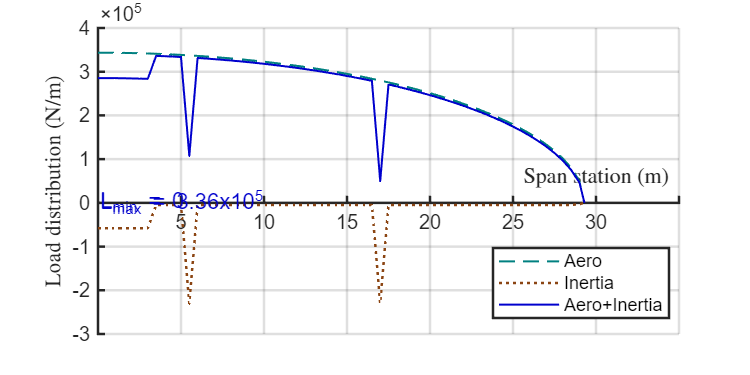

% Plot wing load n = 3.75

figure(1)

clf;

plot(L.Var1, L.Var2, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(L.Var1, L.Var3, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(L.Var1, L.Var4, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'L_{max} = 3.36x10^5';
txt2 = 'L_{min} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

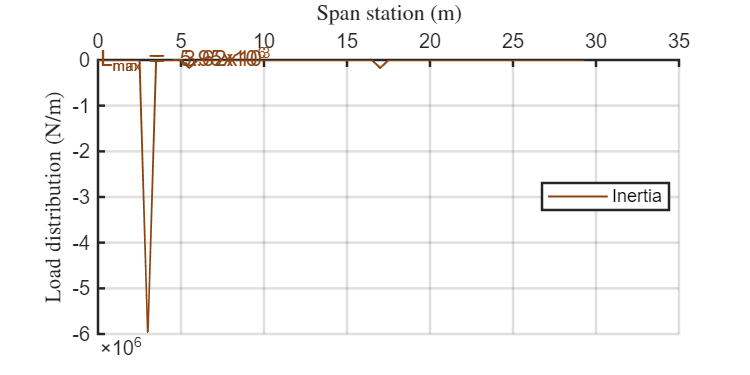

% Plot wing load n = 2.82

figure(2)

clf;

plot(L.Var1, L.Var5, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)

txt1 = 'L_{min} = -5.95x10^6';
txt2 = 'L_{max} = -3.62x10^3';

text(0, 0, txt1, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [139/255 69/255 19/255], 'FontSize', 11)

% Legends
legend("Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

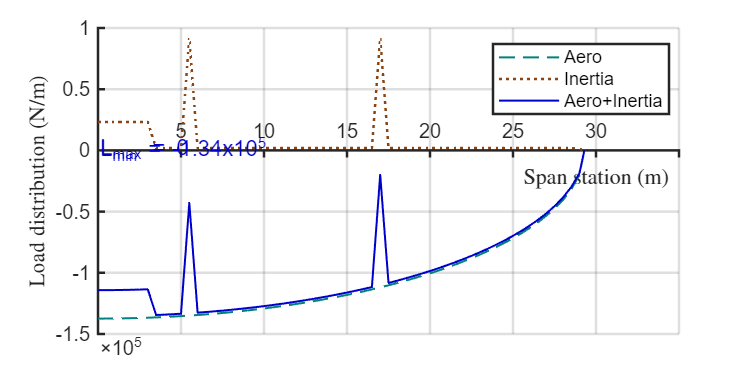

% Plot wing load n = -1.5

figure(3)

clf;

plot(L.Var1, L.Var6, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(L.Var1, L.Var7, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(L.Var1, L.Var8, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'L_{min} = -1.34x10^5';
txt2 = 'L_{max} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

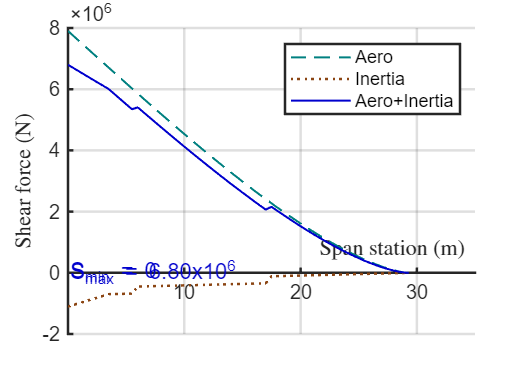

% Plot wing shear n = 3.75

figure(4)

clf;

plot(S.Var1, S.Var2, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(S.Var1, S.Var3, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(S.Var1, S.Var4, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'S_{max} = 6.80x10^6';
txt2 = 'S_{min} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

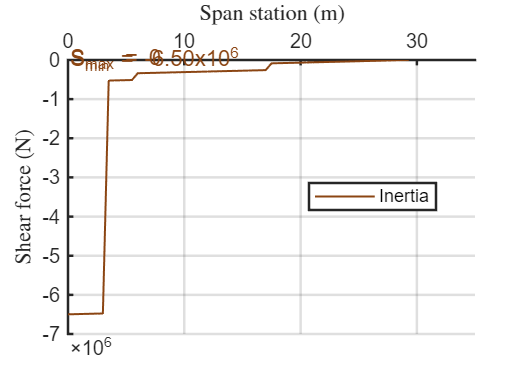

% Plot wing shear n = 2.82

figure(5)

clf;

plot(S.Var1, S.Var5, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)

txt1 = 'S_{min} = -6.50x10^6';
txt2 = 'S_{max} = 0';

text(0, 0, txt1, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [139/255 69/255 19/255], 'FontSize', 11)

% Legends
legend("Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

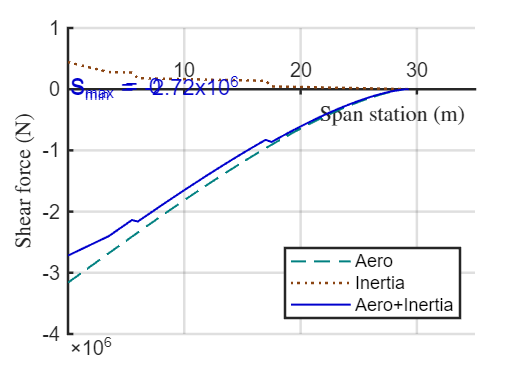

% Plot wing shear n = -1.5

figure(6)

clf;

plot(S.Var1, S.Var6, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(S.Var1, S.Var7, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(S.Var1, S.Var8, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'S_{min} = -2.72x10^6';
txt2 = 'S_{max} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

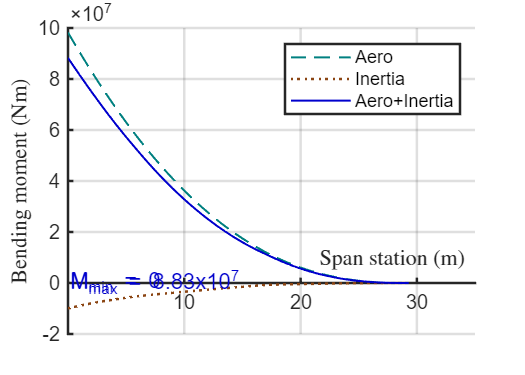

% Plot wing moment n = 3.75

figure(7)

clf;

plot(M.Var1, M.Var2, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(M.Var1, M.Var3, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(M.Var1, M.Var4, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'M_{max} = 8.83x10^7';
txt2 = 'M_{min} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

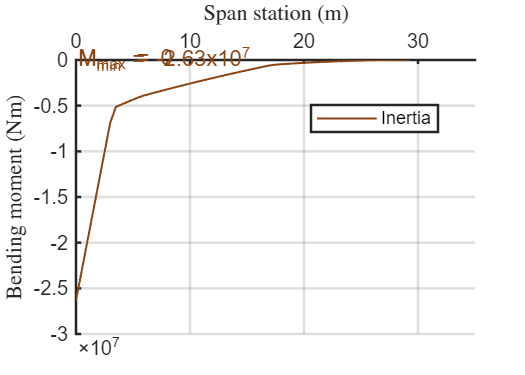

% Plot wing moment n = 2.82

figure(8)

clf;

plot(M.Var1, M.Var5, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)

txt1 = 'M_{min} = -2.63x10^7';
txt2 = 'M_{max} = 0';

text(0, 0, txt1, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [139/255 69/255 19/255], 'FontSize', 11)

% Legends
legend("Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

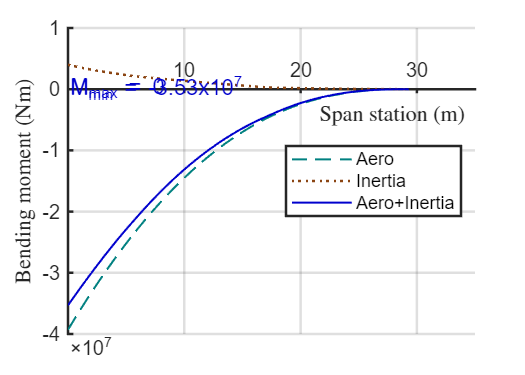

% Plot wing moment n = -1.5

figure(9)

clf;

plot(M.Var1, M.Var6, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(M.Var1, M.Var7, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(M.Var1, M.Var8, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'M_{min} = -3.53x10^7';
txt2 = 'M_{max} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Aero","Inertia", "Aero+Inertia", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

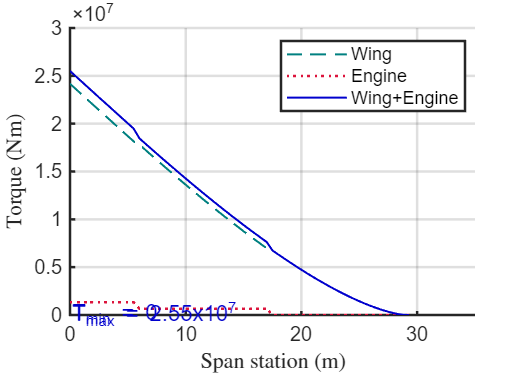

% Plot wing torque n = 3.75

figure(10)

clf;

plot(T.Var1, T.Var2, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(T.Var1, T.Var3, ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25)
hold on
plot(T.Var1, T.Var4, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'T_{max} = 2.55x10^7';
txt2 = 'T_{min} = 0';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Wing","Engine", "Wing+Engine", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

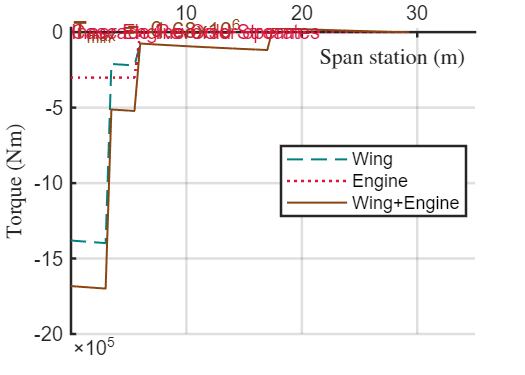

% Plot wing torque n = 2.82

figure(11)

clf;

plot(T.Var1, T.Var5, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(T.Var1, T.Var6, ':', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25)
hold on
plot(T.Var1, T.Var7, '-', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold off

txt1 = 'T_{min} = -1.68x10^6';
txt2 = 'T_{max} = 0';
txt3 = 'Inner Engine Cold Stream';
txt4 = 'Cascade Reverser operates';

text(0, 0, txt1, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [139/255 69/255 19/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [220/255 20/255 60/255], 'FontSize', 10)
text(0, 0, txt4, 'Color', [220/255 20/255 60/255], 'FontSize', 10)

% Legends
legend("Wing","Engine", "Wing+Engine", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

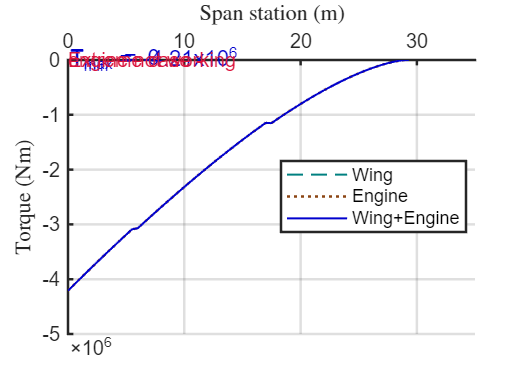

% Plot wing torque n = -1.5

figure(12)

clf;

plot(T.Var1, T.Var8, '--', 'Color', [0/255 128/255 128/255], 'LineWidth', 1)
hold on
plot(T.Var1, T.Var9, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.25)
hold on
plot(T.Var1, T.Var10, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold off

txt1 = 'T_{min} = -4.21x10^6';
txt2 = 'T_{max} = 0';
txt3 = 'Extreme case -';
txt4 = 'engine not working';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [220/255 20/255 60/255], 'FontSize', 10)
text(0, 0, txt4, 'Color', [220/255 20/255 60/255], 'FontSize', 10)

% Legends
legend("Wing","Engine", "Wing+Engine", "Location","best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 35]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

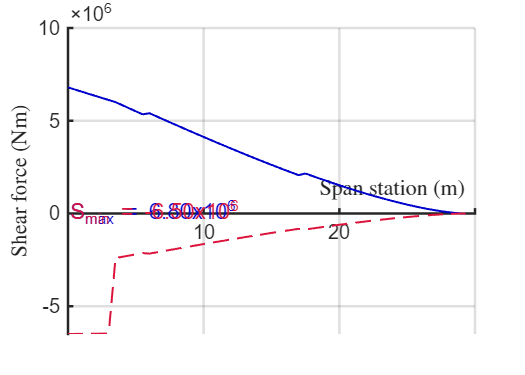

% Plot wing shear

figure(13)

clf;

plot(All.Var1, All.Var2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot(All.Var1, All.Var3, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'S_{max} = 6.80x10^6';
txt2 = 'S_{min} = -6.50x10^6';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Shear force (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 30]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

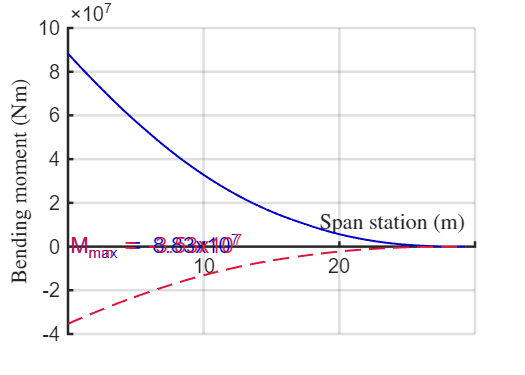

% Plot wing moment

figure(14)

clf;

plot(All.Var1, All.Var4, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot(All.Var1, All.Var5, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'M_{max} = 8.83x10^7';
txt2 = 'M_{min} = -3.53x10^7';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 30]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

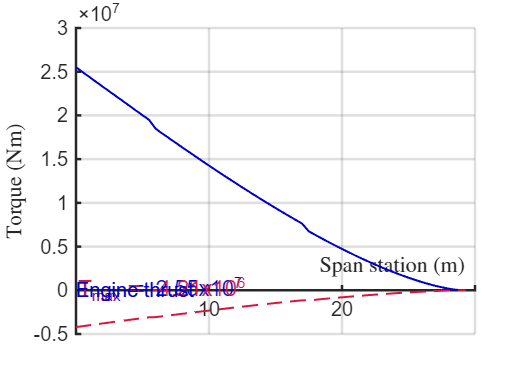

% Plot wing torque

figure(15)

clf;

plot(All.Var1, All.Var6, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot(All.Var1, All.Var7, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold off

txt1 = 'T_{max} = 2.55x10^7';
txt2 = 'T_{min} = -4.21x10^6';

txt3 = 'Engine thrust';
txt4 = 'Engine thrust';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [220/255 20/255 60/255], 'FontSize', 11)
text(0, 0, txt3, 'Color', [0/255 0/255 205/255], 'FontSize', 10)
text(0, 0, txt4, 'Color', [0/255 0/255 205/255], 'FontSize', 10)


% Axis labels with LaTeX font
xlabel('Span station (m)', 'Interpreter', 'latex');
ylabel('Torque (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 30]);
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);